# Test Case - Vehicle1D

mdl = "Vehicle1D_Component_harness_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end
Vehicle1D_Component_harness_setup

## Setup

simIn = Simulink.SimulationInput(mdl);

% Block parameters

simIn = setBlockParameter(simIn, mdl+"/Brake force", Time="300");
simIn = setBlockParameter(simIn, mdl+"/Brake force", Before="0");
simIn = setBlockParameter(simIn, mdl+"/Brake force", After="1000");

simIn = setBlockParameter(simIn, mdl+"/Road grade", Time="200");
simIn = setBlockParameter(simIn, mdl+"/Road grade", Before="-5");
simIn = setBlockParameter(simIn, mdl+"/Road grade", After="-7");

simIn = setBlockParameter(simIn, mdl+"/Axle torque", Time="1");
simIn = setBlockParameter(simIn, mdl+"/Axle torque", Before="0");
simIn = setBlockParameter(simIn, mdl+"/Axle torque", After="0");

% Initial conditions

simIn = setVariable(simIn, "initial.vehicle_speed_kph", 0);

## Run Simulation

% Simulaton stop time
simIn = setModelParameter(simIn, StopTime = "500");

% Run simulation
simOut = sim(simIn);

% Copy simlog to the base workspace
% so that sscexplore can load it.
simlog = simOut.simlog;

% The use of applyToModel below is optional.
% Comment out applyToModel to avoid updating the model file,
% and you can still run simulation.
applyToModel(simIn)

## Visualize Simulation Result

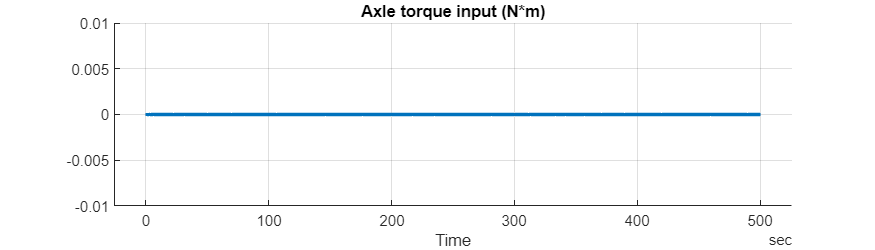

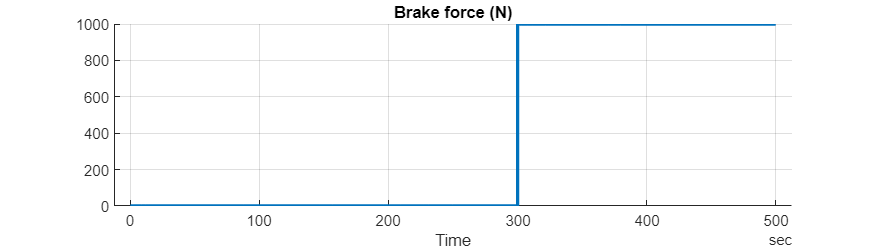

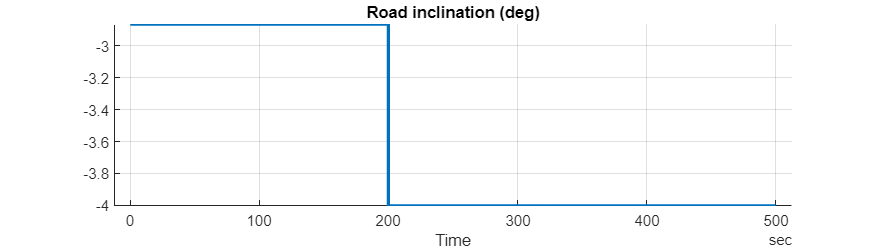

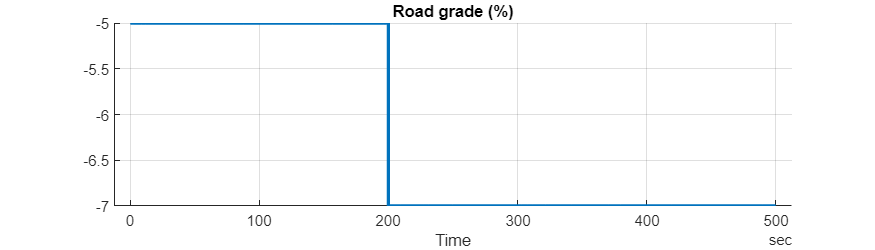

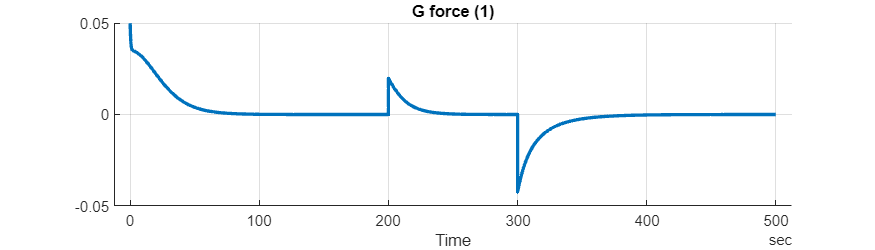

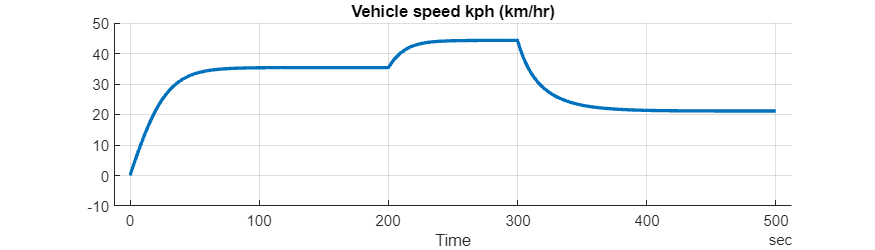

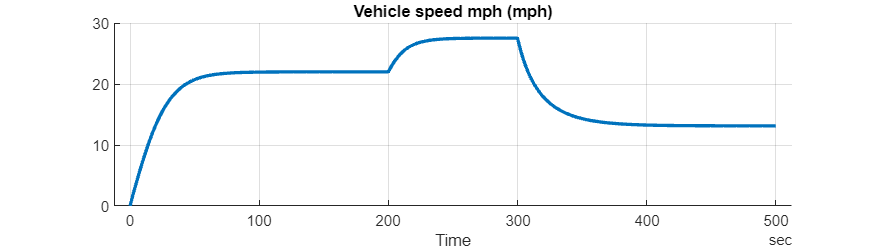

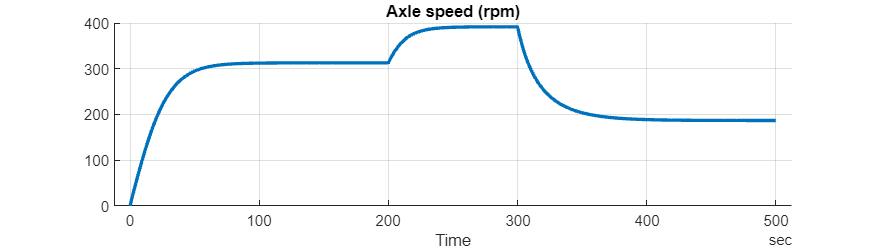

simData = extractTimetable(simOut.logsout);

Vehicle1D_Component_plotResults(SimData = simData, FigureHeight = 200);

*Copyright 2021-2022 The Mathworks, Inc.*